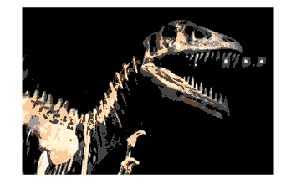

clear all
%Load in the image you want to reproduce
%im = imread('images\roi-dimor-unsplash.jpg');
im = imread('images\dino.jpg');

%Set the amount of pixels you want to use in height and width
height = 200;
width = 300;

%Size of bead
beadHeight = 10;
beadWidth = 10;

% Pick and load in the pallette
% load('SpecRgb20.mat');
% pallette = SpecRgb20;

% load('SpecRgb50.mat');
% pallette = SpecRgb50;

load('SpecRgb100.mat');
pallette = SpecRgb100;

% load('RanRgb21.mat');
% pallette = RanRgb21;

% load('RanRgb51.mat');
% pallette = RanRgb51;

% load('RanRgb100.mat');
% pallette = RanRgb100;


%Create an empty matrix of the given size to put the reproduction into
reproduction = ones(height*beadHeight, width*beadWidth, 3);

%Resize the image to fit with the given size
resizedIm = imresize(im, [height width]);
imLab = rgb2lab(resizedIm);
%imshow(resizedIm)


%Convert the pallette into lab values
pallette = pallette./255;
palletteLab = rgb2lab(pallette);

%Go through each pixle of the image and convert it's rgb values to Lab
%values. Compare the Lab values of the current pixle to those in the database using
%deltaE, the closest value is the colour you pick. Place that colour
%bead in the corresponding location of the reproduction matrix/image.

for i = 1:height

    for j = 1:width
            
        lab(1,:) = imLab(i,j,:);

        labm = repmat(lab, [length(palletteLab), 1]);

        difference = sqrt((labm(:,1)-palletteLab(:,1)).^2 +(labm(:,2)-palletteLab(:,2)).^2 +(labm(:,3)-palletteLab(:,3)).^2);

        minPos = find(difference == min(difference));

        %reproduction((i-1)*S+1:i*S,(j-1)*S+1:j*S)=PRIMITIV;
        %S = beadheight

        %reproduction(i,j,:) = pallette(minPos(1,:),:);
        bead = makeBeadBox(pallette, minPos, beadHeight, beadWidth);
            
        reproduction((i-1)*beadHeight+1:i*beadHeight,(j-1)*beadHeight+1:j*beadHeight,:)= bead;

    end
    
end

imshow(reproduction)

beadHeight = 29;
beadWidth = beadHeight;
%binaryImage = zeros(height, width);
hbh = beadHeight/2;
hbw = beadWidth/2;
bead = zeros(beadHeight,beadWidth);
n = 0;

 for i = 1:hbh
     
    if mod(beadWidth,2) == 0

    bead(i, (hbw-n):(hbw+1+n)) = 1;

    bead(i+ hbw -1, (1+n):(beadWidth-n)) = 1;

    n = n + 1;

    elseif mod(beadWidth,2) ~= 0

    bead(i, (hbw+0.5-n):(hbw+0.5+n)) = 1;
    bead(i+ hbw -1.5, (1+n):(beadWidth-n)) = 1;
    n = n + 1;
    end
        
 end
 imshow(bead)



reproductionLab = rgb2lab(reproduction);
resizedImAgain = imresize(resizedIm,[length(reproductionLab(:,1,:)) length(reproductionLab(1,:,:))]);
originalLab = rgb2lab(resizedImAgain);

difference = sqrt((reproductionLab(:,:,1)-originalLab(:,:,1)).^2 +(reproductionLab(:,:,2)-originalLab(:,:,2)).^2 +(reproductionLab(:,:,3)-originalLab(:,:,3)).^2);

maxVal = max(max(difference));
meanVal = mean(mean(difference));
minVal = min(min(difference));


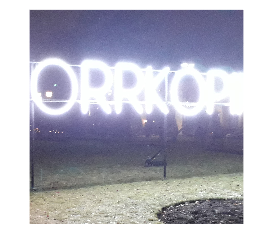

%Cropping the images so they are all same width and height
im = imread('images\norrköping.jpg');

targetSize = [2000 2000];
%targetSize = [1400 1400];

r = centerCropWindow2d(size(im),targetSize);

J = imcrop(im,r);
imshow(J)

imwrite(J,'orrköpi.png')

%s-cielab calculations
% input = imread('images\dino.png');
% repro = imread('dino_beadSize_20_pallette_spec100.png');
% ppi = 120;
% distance = 20;
% sampPerDeg = ppi * distance * tan(pi/180);
% 
% scielab_im = scielab(sampPerDeg,input, repro, D65, 'xyz');
% 
% quality_scielab_im = mean(mean(scielab_im));

load('RanRgb100.mat');
pallette = RanRgb100;
pallette = pallette./255;
palletteLab = rgb2lab(pallette);

L = palletteLab(:,1);
A = palletteLab(:,2);
B = palletteLab(:,3);


im = imread("images\swing.png");
colorAmount = 22;

[im_no_dither,map] = rgb2ind(im,colorAmount,'nodither');

mapLab = rgb2lab(map);
maxPos = zeros(size(palletteLab));
height = length(im_no_dither(1,:,:));
width = height;

n = 1;

mapLabL = mapLab(:,1);
mapLabA = mapLab(:,2);
mapLabB = mapLab(:,3);

THRESHOLD = 15;

swing_RanRgb20 = zeros(size(mapLab));

for i = 1:colorAmount
    for j = 1:100
        lab(1,:) = mapLab(i,:);

        labm = repmat(lab, [length(palletteLab), 1]);

        difference = sqrt((labm(:,1)-palletteLab(:,1)).^2 +(labm(:,2)-palletteLab(:,2)).^2 +(labm(:,3)-palletteLab(:,3)).^2);

        minPos = find(difference == min(difference))

        swing_RanRgb20(i,:) = pallette(minPos(1,:),:);
    end

end

i = 1

j = 1

minPos = 1

i = 1

j = 2

minPos = 1

i = 1

j = 3

minPos = 1

i = 1

j = 4

minPos = 1

i = 1

j = 5

minPos = 1

i = 1

j = 6

minPos = 1

i = 1

j = 7

minPos = 1

i = 1

j = 8

minPos = 1

i = 1

j = 9

minPos = 1

i = 1

j = 10

minPos = 1

i = 1

j = 11

minPos = 1

i = 1

j = 12

minPos = 1

i = 1

j = 13

minPos = 1

i = 1

j = 14

minPos = 1

i = 1

j = 15

minPos = 1

i = 1

j = 16

minPos = 1

i = 1

j = 17

minPos = 1

i = 1

j = 18

minPos = 1

i = 1

j = 19

minPos = 1

i = 1

j = 20

minPos = 1

i = 1

j = 21

minPos = 1

i = 1

j = 22

minPos = 1

i = 1

j = 23

minPos = 1

i = 1

j = 24

minPos = 1

i = 1

j = 25

minPos = 1

i = 1

j = 26

minPos = 1

i = 1

j = 27

minPos = 1

i = 1

j = 28

minPos = 1

i = 1

j = 29

minPos = 1

i = 1

j = 30

minPos = 1

i = 1

j = 31

minPos = 1

i = 1

j = 32

minPos = 1

i = 1

j = 33

minPos = 1

i = 1

j = 34

minPos = 1

i = 1

j = 35

minPos = 1

i = 1

j = 36

minPos = 1

i = 1

j = 37

minPos = 1

i = 1

j = 38

minPos = 1

i = 1

j = 39

minPos = 1

i = 1

j = 40

minPos = 1

i = 1

j = 41

minPos = 1

i = 1

j = 42

minPos = 1

i = 1

j = 43

minPos = 1

i = 1

j = 44

minPos = 1

i = 1

j = 45

minPos = 1

i = 1

j = 46

minPos = 1

i = 1

j = 47

minPos = 1

i = 1

j = 48

minPos = 1

i = 1

j = 49

minPos = 1

i = 1

j = 50

minPos = 1

i = 1

j = 51

minPos = 1

i = 1

j = 52

minPos = 1

i = 1

j = 53

minPos = 1

i = 1

j = 54

minPos = 1

i = 1

j = 55

minPos = 1

i = 1

j = 56

minPos = 1

i = 1

j = 57

minPos = 1

i = 1

j = 58

minPos = 1

i = 1

j = 59

minPos = 1

i = 1

j = 60

minPos = 1

i = 1

j = 61

minPos = 1

i = 1

j = 62

minPos = 1

i = 1

j = 63

minPos = 1

i = 1

j = 64

minPos = 1

i = 1

j = 65

minPos = 1

i = 1

j = 66

minPos = 1

i = 1

j = 67

minPos = 1

i = 1

j = 68

minPos = 1

i = 1

j = 69

minPos = 1

i = 1

j = 70

minPos = 1

i = 1

j = 71

minPos = 1

i = 1

j = 72

minPos = 1

i = 1

j = 73

minPos = 1

i = 1

j = 74

minPos = 1

i = 1

j = 75

minPos = 1

i = 1

j = 76

minPos = 1

i = 1

j = 77

minPos = 1

i = 1

j = 78

minPos = 1

i = 1

j = 79

minPos = 1

i = 1

j = 80

minPos = 1

i = 1

j = 81

minPos = 1

i = 1

j = 82

minPos = 1

i = 1

j = 83

minPos = 1

i = 1

j = 84

minPos = 1

i = 1

j = 85

minPos = 1

i = 1

j = 86

minPos = 1

i = 1

j = 87

minPos = 1

i = 1

j = 88

minPos = 1

i = 1

j = 89

minPos = 1

i = 1

j = 90

minPos = 1

i = 1

j = 91

minPos = 1

i = 1

j = 92

minPos = 1

i = 1

j = 93

minPos = 1

i = 1

j = 94

minPos = 1

i = 1

j = 95

minPos = 1

i = 1

j = 96

minPos = 1

i = 1

j = 97

minPos = 1

i = 1

j = 98

minPos = 1

i = 1

j = 99

minPos = 1

i = 1

j = 100

minPos = 1

i = 2

j = 1

minPos = 28

i = 2

j = 2

minPos = 28

i = 2

j = 3

minPos = 28

i = 2

j = 4

minPos = 28

i = 2

j = 5

minPos = 28

i = 2

j = 6

minPos = 28

i = 2

j = 7

minPos = 28

i = 2

j = 8

minPos = 28

i = 2

j = 9

minPos = 28

i = 2

j = 10

minPos = 28

i = 2

j = 11

minPos = 28

i = 2

j = 12

minPos = 28

i = 2

j = 13

minPos = 28

i = 2

j = 14

minPos = 28

i = 2

j = 15

minPos = 28

i = 2

j = 16

minPos = 28

i = 2

j = 17

minPos = 28

i = 2

j = 18

minPos = 28

i = 2

j = 19

minPos = 28

i = 2

j = 20

minPos = 28

i = 2

j = 21

minPos = 28

i = 2

j = 22

minPos = 28

i = 2

j = 23

minPos = 28

i = 2

j = 24

minPos = 28

i = 2

j = 25

minPos = 28

i = 2

j = 26

minPos = 28

i = 2

j = 27

minPos = 28

i = 2

j = 28

minPos = 28

i = 2

j = 29

minPos = 28

i = 2

j = 30

minPos = 28

i = 2

j = 31

minPos = 28

i = 2

j = 32

minPos = 28

i = 2

j = 33

minPos = 28

i = 2

j = 34

minPos = 28

i = 2

j = 35

minPos = 28

i = 2

j = 36

minPos = 28

i = 2

j = 37

minPos = 28

i = 2

j = 38

minPos = 28

i = 2

j = 39

minPos = 28

i = 2

j = 40

minPos = 28

i = 2

j = 41

minPos = 28

i = 2

j = 42

minPos = 28

i = 2

j = 43

minPos = 28

i = 2

j = 44

minPos = 28

i = 2

j = 45

minPos = 28

i = 2

j = 46

minPos = 28

i = 2

j = 47

minPos = 28

i = 2

j = 48

minPos = 28

i = 2

j = 49

minPos = 28

i = 2

j = 50

minPos = 28

i = 2

j = 51

minPos = 28

i = 2

j = 52

minPos = 28

i = 2

j = 53

minPos = 28

i = 2

j = 54

minPos = 28

i = 2

j = 55

minPos = 28

i = 2

j = 56

minPos = 28

i = 2

j = 57

minPos = 28

i = 2

j = 58

minPos = 28

i = 2

j = 59

minPos = 28

i = 2

j = 60

minPos = 28

i = 2

j = 61

minPos = 28

i = 2

j = 62

minPos = 28

i = 2

j = 63

minPos = 28

i = 2

j = 64

minPos = 28

i = 2

j = 65

minPos = 28

i = 2

j = 66

minPos = 28

i = 2

j = 67

minPos = 28

i = 2

j = 68

minPos = 28

i = 2

j = 69

minPos = 28

i = 2

j = 70

minPos = 28

i = 2

j = 71

minPos = 28

i = 2

j = 72

minPos = 28

i = 2

j = 73

minPos = 28

i = 2

j = 74

minPos = 28

i = 2

j = 75

minPos = 28

i = 2

j = 76

minPos = 28

i = 2

j = 77

minPos = 28

i = 2

j = 78

minPos = 28

i = 2

j = 79

minPos = 28

i = 2

j = 80

minPos = 28

i = 2

j = 81

minPos = 28

i = 2

j = 82

minPos = 28

i = 2

j = 83

minPos = 28

i = 2

j = 84

minPos = 28

i = 2

j = 85

minPos = 28

i = 2

j = 86

minPos = 28

i = 2

j = 87

minPos = 28

i = 2

j = 88

minPos = 28

i = 2

j = 89

minPos = 28

i = 2

j = 90

minPos = 28

i = 2

j = 91

minPos = 28

i = 2

j = 92

minPos = 28

i = 2

j = 93

minPos = 28

i = 2

j = 94

minPos = 28

i = 2

j = 95

minPos = 28

i = 2

j = 96

minPos = 28

i = 2

j = 97

minPos = 28

i = 2

j = 98

minPos = 28

i = 2

j = 99

minPos = 28

i = 2

j = 100

minPos = 28

i = 3

j = 1

minPos = 71

i = 3

j = 2

minPos = 71

i = 3

j = 3

minPos = 71

i = 3

j = 4

minPos = 71

i = 3

j = 5

minPos = 71

i = 3

j = 6

minPos = 71

i = 3

j = 7

minPos = 71

i = 3

j = 8

minPos = 71

i = 3

j = 9

minPos = 71

i = 3

j = 10

minPos = 71

i = 3

j = 11

minPos = 71

i = 3

j = 12

minPos = 71

i = 3

j = 13

minPos = 71

i = 3

j = 14

minPos = 71

i = 3

j = 15

minPos = 71

i = 3

j = 16

minPos = 71

i = 3

j = 17

minPos = 71

i = 3

j = 18

minPos = 71

i = 3

j = 19

minPos = 71

i = 3

j = 20

minPos = 71

i = 3

j = 21

minPos = 71

i = 3

j = 22

minPos = 71

i = 3

j = 23

minPos = 71

i = 3

j = 24

minPos = 71

i = 3

j = 25

minPos = 71

i = 3

j = 26

minPos = 71

i = 3

j = 27

minPos = 71

i = 3

j = 28

minPos = 71

i = 3

j = 29

minPos = 71

i = 3

j = 30

minPos = 71

i = 3

j = 31

minPos = 71

i = 3

j = 32

minPos = 71

i = 3

j = 33

minPos = 71

i = 3

j = 34

minPos = 71

i = 3

j = 35

minPos = 71

i = 3

j = 36

minPos = 71

i = 3

j = 37

minPos = 71

i = 3

j = 38

minPos = 71

i = 3

j = 39

minPos = 71

i = 3

j = 40

minPos = 71

i = 3

j = 41

minPos = 71

i = 3

j = 42

minPos = 71

i = 3

j = 43

minPos = 71

i = 3

j = 44

minPos = 71

i = 3

j = 45

minPos = 71

i = 3

j = 46

minPos = 71

i = 3

j = 47

minPos = 71

i = 3

j = 48

minPos = 71

i = 3

j = 49

minPos = 71

i = 3

j = 50

minPos = 71

i = 3

j = 51

minPos = 71

i = 3

j = 52

minPos = 71

i = 3

j = 53

minPos = 71

i = 3

j = 54

minPos = 71

i = 3

j = 55

minPos = 71

i = 3

j = 56

minPos = 71

i = 3

j = 57

minPos = 71

i = 3

j = 58

minPos = 71

i = 3

j = 59

minPos = 71

i = 3

j = 60

minPos = 71

i = 3

j = 61

minPos = 71

i = 3

j = 62

minPos = 71

i = 3

j = 63

minPos = 71

i = 3

j = 64

minPos = 71

i = 3

j = 65

minPos = 71

i = 3

j = 66

minPos = 71

i = 3

j = 67

minPos = 71

i = 3

j = 68

minPos = 71

i = 3

j = 69

minPos = 71

i = 3

j = 70

minPos = 71

i = 3

j = 71

minPos = 71

i = 3

j = 72

minPos = 71

i = 3

j = 73

minPos = 71

i = 3

j = 74

minPos = 71

i = 3

j = 75

minPos = 71

i = 3

j = 76

minPos = 71

i = 3

j = 77

minPos = 71

i = 3

j = 78

minPos = 71

i = 3

j = 79

minPos = 71

i = 3

j = 80

minPos = 71

i = 3

j = 81

minPos = 71

i = 3

j = 82

minPos = 71

i = 3

j = 83

minPos = 71

i = 3

j = 84

minPos = 71

i = 3

j = 85

minPos = 71

i = 3

j = 86

minPos = 71

i = 3

j = 87

minPos = 71

i = 3

j = 88

minPos = 71

i = 3

j = 89

minPos = 71

i = 3

j = 90

minPos = 71

i = 3

j = 91

minPos = 71

i = 3

j = 92

minPos = 71

i = 3

j = 93

minPos = 71

i = 3

j = 94

minPos = 71

i = 3

j = 95

minPos = 71

i = 3

j = 96

minPos = 71

i = 3

j = 97

minPos = 71

i = 3

j = 98

minPos = 71

i = 3

j = 99

minPos = 71

i = 3

j = 100

minPos = 71

i = 4

j = 1

minPos = 24

i = 4

j = 2

minPos = 24

i = 4

j = 3

minPos = 24

i = 4

j = 4

minPos = 24

i = 4

j = 5

minPos = 24

i = 4

j = 6

minPos = 24

i = 4

j = 7

minPos = 24

i = 4

j = 8

minPos = 24

i = 4

j = 9

minPos = 24

i = 4

j = 10

minPos = 24

i = 4

j = 11

minPos = 24

i = 4

j = 12

minPos = 24

i = 4

j = 13

minPos = 24

i = 4

j = 14

minPos = 24

i = 4

j = 15

minPos = 24

i = 4

j = 16

minPos = 24

i = 4

j = 17

minPos = 24

i = 4

j = 18

minPos = 24

i = 4

j = 19

minPos = 24

i = 4

j = 20

minPos = 24

i = 4

j = 21

minPos = 24

i = 4

j = 22

minPos = 24

i = 4

j = 23

minPos = 24

i = 4

j = 24

minPos = 24

i = 4

j = 25

minPos = 24

i = 4

j = 26

minPos = 24

i = 4

j = 27

minPos = 24

i = 4

j = 28

minPos = 24

i = 4

j = 29

minPos = 24

i = 4

j = 30

minPos = 24

i = 4

j = 31

minPos = 24

i = 4

j = 32

minPos = 24

i = 4

j = 33

minPos = 24

i = 4

j = 34

minPos = 24

i = 4

j = 35

minPos = 24

i = 4

j = 36

minPos = 24

i = 4

j = 37

minPos = 24

i = 4

j = 38

minPos = 24

i = 4

j = 39

minPos = 24

i = 4

j = 40

minPos = 24

i = 4

j = 41

minPos = 24

i = 4

j = 42

minPos = 24

i = 4

j = 43

minPos = 24

i = 4

j = 44

minPos = 24

i = 4

j = 45

minPos = 24

i = 4

j = 46

minPos = 24

i = 4

j = 47

minPos = 24

i = 4

j = 48

minPos = 24

i = 4

j = 49

minPos = 24

i = 4

j = 50

minPos = 24

i = 4

j = 51

minPos = 24

i = 4

j = 52

minPos = 24

i = 4

j = 53

minPos = 24

i = 4

j = 54

minPos = 24

i = 4

j = 55

minPos = 24

i = 4

j = 56

minPos = 24

i = 4

j = 57

minPos = 24

i = 4

j = 58

minPos = 24

i = 4

j = 59

minPos = 24

i = 4

j = 60

minPos = 24

i = 4

j = 61

minPos = 24

i = 4

j = 62

minPos = 24

i = 4

j = 63

minPos = 24

i = 4

j = 64

minPos = 24

i = 4

j = 65

minPos = 24

i = 4

j = 66

minPos = 24

i = 4

j = 67

minPos = 24

i = 4

j = 68

minPos = 24

i = 4

j = 69

minPos = 24

i = 4

j = 70

minPos = 24

i = 4

j = 71

minPos = 24

i = 4

j = 72

minPos = 24

i = 4

j = 73

minPos = 24

i = 4

j = 74

minPos = 24

i = 4

j = 75

minPos = 24

i = 4

j = 76

minPos = 24

i = 4

j = 77

minPos = 24

i = 4

j = 78

minPos = 24

i = 4

j = 79

minPos = 24

i = 4

j = 80

minPos = 24

i = 4

j = 81

minPos = 24

i = 4

j = 82

minPos = 24

i = 4

j = 83

minPos = 24

i = 4

j = 84

minPos = 24

i = 4

j = 85

minPos = 24

i = 4

j = 86

minPos = 24

i = 4

j = 87

minPos = 24

i = 4

j = 88

minPos = 24

i = 4

j = 89

minPos = 24

i = 4

j = 90

minPos = 24

i = 4

j = 91

minPos = 24

i = 4

j = 92

minPos = 24

i = 4

j = 93

minPos = 24

i = 4

j = 94

minPos = 24

i = 4

j = 95

minPos = 24

i = 4

j = 96

minPos = 24

i = 4

j = 97

minPos = 24

i = 4

j = 98

minPos = 24

i = 4

j = 99

minPos = 24

i = 4

j = 100

minPos = 24

i = 5

j = 1

minPos = 86

i = 5

j = 2

minPos = 86

i = 5

j = 3

minPos = 86

i = 5

j = 4

minPos = 86

i = 5

j = 5

minPos = 86

i = 5

j = 6

minPos = 86

i = 5

j = 7

minPos = 86

i = 5

j = 8

minPos = 86

i = 5

j = 9

minPos = 86

i = 5

j = 10

minPos = 86

i = 5

j = 11

minPos = 86

i = 5

j = 12

minPos = 86

i = 5

j = 13

minPos = 86

i = 5

j = 14

minPos = 86

i = 5

j = 15

minPos = 86

i = 5

j = 16

minPos = 86

i = 5

j = 17

minPos = 86

i = 5

j = 18

minPos = 86

i = 5

j = 19

minPos = 86

i = 5

j = 20

minPos = 86

i = 5

j = 21

minPos = 86

i = 5

j = 22

minPos = 86

i = 5

j = 23

minPos = 86

i = 5

j = 24

minPos = 86

i = 5

j = 25

minPos = 86

i = 5

j = 26

minPos = 86

i = 5

j = 27

minPos = 86

i = 5

j = 28

minPos = 86

i = 5

j = 29

minPos = 86

i = 5

j = 30

minPos = 86

i = 5

j = 31

minPos = 86

i = 5

j = 32

minPos = 86

i = 5

j = 33

minPos = 86

i = 5

j = 34

minPos = 86

i = 5

j = 35

minPos = 86

i = 5

j = 36

minPos = 86

i = 5

j = 37

minPos = 86

i = 5

j = 38

minPos = 86

i = 5

j = 39

minPos = 86

i = 5

j = 40

minPos = 86

i = 5

j = 41

minPos = 86

i = 5

j = 42

minPos = 86

i = 5

j = 43

minPos = 86

i = 5

j = 44

minPos = 86

i = 5

j = 45

minPos = 86

i = 5

j = 46

minPos = 86

i = 5

j = 47

minPos = 86

i = 5

j = 48

minPos = 86

i = 5

j = 49

minPos = 86

i = 5

j = 50

minPos = 86

i = 5

j = 51

minPos = 86

i = 5

j = 52

minPos = 86

i = 5

j = 53

minPos = 86

i = 5

j = 54

minPos = 86

i = 5

j = 55

minPos = 86

i = 5

j = 56

minPos = 86

i = 5

j = 57

minPos = 86

i = 5

j = 58

minPos = 86

i = 5

j = 59

minPos = 86

i = 5

j = 60

minPos = 86

i = 5

j = 61

minPos = 86

i = 5

j = 62

minPos = 86

i = 5

j = 63

minPos = 86

i = 5

j = 64

minPos = 86

i = 5

j = 65

minPos = 86

i = 5

j = 66

minPos = 86

i = 5

j = 67

minPos = 86

i = 5

j = 68

minPos = 86

i = 5

j = 69

minPos = 86

i = 5

j = 70

minPos = 86

i = 5

j = 71

minPos = 86

i = 5

j = 72

minPos = 86

i = 5

j = 73

minPos = 86

i = 5

j = 74

minPos = 86

i = 5

j = 75

minPos = 86

i = 5

j = 76

minPos = 86

i = 5

j = 77

minPos = 86

i = 5

j = 78

minPos = 86

i = 5

j = 79

minPos = 86

i = 5

j = 80

minPos = 86

i = 5

j = 81

minPos = 86

i = 5

j = 82

minPos = 86

i = 5

j = 83

minPos = 86

i = 5

j = 84

minPos = 86

i = 5

j = 85

minPos = 86

i = 5

j = 86

minPos = 86

i = 5

j = 87

minPos = 86

i = 5

j = 88

minPos = 86

i = 5

j = 89

minPos = 86

i = 5

j = 90

minPos = 86

i = 5

j = 91

minPos = 86

i = 5

j = 92

minPos = 86

i = 5

j = 93

minPos = 86

i = 5

j = 94

minPos = 86

i = 5

j = 95

minPos = 86

i = 5

j = 96

minPos = 86

i = 5

j = 97

minPos = 86

i = 5

j = 98

minPos = 86

i = 5

j = 99

minPos = 86

i = 5

j = 100

minPos = 86

i = 6

j = 1

minPos = 40

i = 6

j = 2

minPos = 40

i = 6

j = 3

minPos = 40

i = 6

j = 4

minPos = 40

i = 6

j = 5

minPos = 40

i = 6

j = 6

minPos = 40

i = 6

j = 7

minPos = 40

i = 6

j = 8

minPos = 40

i = 6

j = 9

minPos = 40

i = 6

j = 10

minPos = 40

i = 6

j = 11

minPos = 40

i = 6

j = 12

minPos = 40

i = 6

j = 13

minPos = 40

i = 6

j = 14

minPos = 40

i = 6

j = 15

minPos = 40

i = 6

j = 16

minPos = 40

i = 6

j = 17

minPos = 40

i = 6

j = 18

minPos = 40

i = 6

j = 19

minPos = 40

i = 6

j = 20

minPos = 40

i = 6

j = 21

minPos = 40

i = 6

j = 22

minPos = 40

i = 6

j = 23

minPos = 40

i = 6

j = 24

minPos = 40

i = 6

j = 25

minPos = 40

i = 6

j = 26

minPos = 40

i = 6

j = 27

minPos = 40

i = 6

j = 28

minPos = 40

i = 6

j = 29

minPos = 40

i = 6

j = 30

minPos = 40

i = 6

j = 31

minPos = 40

i = 6

j = 32

minPos = 40

i = 6

j = 33

minPos = 40

i = 6

j = 34

minPos = 40

i = 6

j = 35

minPos = 40

i = 6

j = 36

minPos = 40

i = 6

j = 37

minPos = 40

i = 6

j = 38

minPos = 40

i = 6

j = 39

minPos = 40

i = 6

j = 40

minPos = 40

i = 6

j = 41

minPos = 40

i = 6

j = 42

minPos = 40

i = 6

j = 43

minPos = 40

i = 6

j = 44

minPos = 40

i = 6

j = 45

minPos = 40

i = 6

j = 46

minPos = 40

i = 6

j = 47

minPos = 40

i = 6

j = 48

minPos = 40

i = 6

j = 49

minPos = 40

i = 6

j = 50

minPos = 40

i = 6

j = 51

minPos = 40

i = 6

j = 52

minPos = 40

i = 6

j = 53

minPos = 40

i = 6

j = 54

minPos = 40

i = 6

j = 55

minPos = 40

i = 6

j = 56

minPos = 40

i = 6

j = 57

minPos = 40

i = 6

j = 58

minPos = 40

i = 6

j = 59

minPos = 40

i = 6

j = 60

minPos = 40

i = 6

j = 61

minPos = 40

i = 6

j = 62

minPos = 40

i = 6

j = 63

minPos = 40

i = 6

j = 64

minPos = 40

i = 6

j = 65

minPos = 40

i = 6

j = 66

minPos = 40

i = 6

j = 67

minPos = 40

i = 6

j = 68

minPos = 40

i = 6

j = 69

minPos = 40

i = 6

j = 70

minPos = 40

i = 6

j = 71

minPos = 40

i = 6

j = 72

minPos = 40

i = 6

j = 73

minPos = 40

i = 6

j = 74

minPos = 40

i = 6

j = 75

minPos = 40

i = 6

j = 76

minPos = 40

i = 6

j = 77

minPos = 40

i = 6

j = 78

minPos = 40

i = 6

j = 79

minPos = 40

i = 6

j = 80

minPos = 40

i = 6

j = 81

minPos = 40

i = 6

j = 82

minPos = 40

i = 6

j = 83

minPos = 40

i = 6

j = 84

minPos = 40

i = 6

j = 85

minPos = 40

i = 6

j = 86

minPos = 40

i = 6

j = 87

minPos = 40

i = 6

j = 88

minPos = 40

i = 6

j = 89

minPos = 40

i = 6

j = 90

minPos = 40

i = 6

j = 91

minPos = 40

i = 6

j = 92

minPos = 40

i = 6

j = 93

minPos = 40

i = 6

j = 94

minPos = 40

i = 6

j = 95

minPos = 40

i = 6

j = 96

minPos = 40

i = 6

j = 97

minPos = 40

i = 6

j = 98

minPos = 40

i = 6

j = 99

minPos = 40

i = 6

j = 100

minPos = 40

i = 7

j = 1

minPos = 51

i = 7

j = 2

minPos = 51

i = 7

j = 3

minPos = 51

i = 7

j = 4

minPos = 51

i = 7

j = 5

minPos = 51

i = 7

j = 6

minPos = 51

i = 7

j = 7

minPos = 51

i = 7

j = 8

minPos = 51

i = 7

j = 9

minPos = 51

i = 7

j = 10

minPos = 51

i = 7

j = 11

minPos = 51

i = 7

j = 12

minPos = 51

i = 7

j = 13

minPos = 51

i = 7

j = 14

minPos = 51

i = 7

j = 15

minPos = 51

i = 7

j = 16

minPos = 51

i = 7

j = 17

minPos = 51

i = 7

j = 18

minPos = 51

i = 7

j = 19

minPos = 51

i = 7

j = 20

minPos = 51

i = 7

j = 21

minPos = 51

i = 7

j = 22

minPos = 51

i = 7

j = 23

minPos = 51

i = 7

j = 24

minPos = 51

i = 7

j = 25

minPos = 51

i = 7

j = 26

minPos = 51

i = 7

j = 27

minPos = 51

i = 7

j = 28

minPos = 51

i = 7

j = 29

minPos = 51

i = 7

j = 30

minPos = 51

i = 7

j = 31

minPos = 51

i = 7

j = 32

minPos = 51

i = 7

j = 33

minPos = 51

i = 7

j = 34

minPos = 51

i = 7

j = 35

minPos = 51

i = 7

j = 36

minPos = 51

i = 7

j = 37

minPos = 51

i = 7

j = 38

minPos = 51

i = 7

j = 39

minPos = 51

i = 7

j = 40

minPos = 51

i = 7

j = 41

minPos = 51

i = 7

j = 42

minPos = 51

i = 7

j = 43

minPos = 51

i = 7

j = 44

minPos = 51

i = 7

j = 45

minPos = 51

i = 7

j = 46

minPos = 51

i = 7

j = 47

minPos = 51

i = 7

j = 48

minPos = 51

i = 7

j = 49

minPos = 51

i = 7

j = 50

minPos = 51

i = 7

j = 51

minPos = 51

i = 7

j = 52

minPos = 51

i = 7

j = 53

minPos = 51

i = 7

j = 54

minPos = 51

i = 7

j = 55

minPos = 51

i = 7

j = 56

minPos = 51

i = 7

j = 57

minPos = 51

i = 7

j = 58

minPos = 51

i = 7

j = 59

minPos = 51

i = 7

j = 60

minPos = 51

i = 7

j = 61

minPos = 51

i = 7

j = 62

minPos = 51

i = 7

j = 63

minPos = 51

i = 7

j = 64

minPos = 51

i = 7

j = 65

minPos = 51

i = 7

j = 66

minPos = 51


new = sortrows(swing_SpecRgb48)

